# Изучение тембра на практике

# 1. Извлечение гармоник из спектра

## Красницкий Никита

Темб - есть окрас музыкального заука, который может быть описан отношением амплитуд гармоник звука и их временными зависимостями. Для исследования тембра возьму в пример извлеченный звук гитарной струны и эксперементально найду математическое описание тембра. После чего попробую искусственно повлиять на тембр и синтезировать новое звучание.

Загружаю аудиофрагмент звукоизвлечения басовой ноты РЕ и вывожу на графиках левый и правый канал

clear all
close all
[x, fs] = audioread('Sound2.m4a');
sound(x, fs);

Что бы получить переменную соответствующую времени делаю следующее. Нахожу временной интервал между отчетами (dt). Через время между отчетами и кол-вом отчетов получаю время длительности сигнала (Ts). Создаю переменную времени (t)

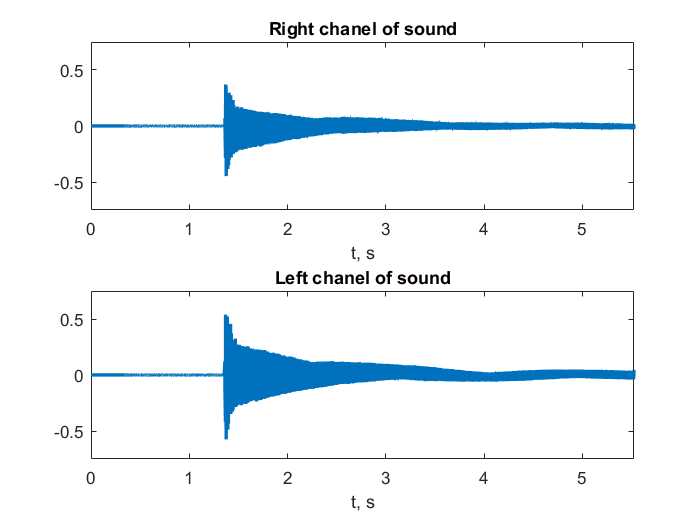

dt = 1/fs;
N  = length(x);
Ts = (N-1)*dt;
t  = 0:dt:Ts;

figure
subplot(2,1,1);
plot(t, x(:,1), 'LineWidth', 2);     
ylim([-0.75 0.75]);
xlim([0 t(end)]);
title('Right chanel of sound');
xlabel('t, s');

subplot(2,1,2);
plot(t, x(:,2), 'LineWidth', 2); 
ylim([-0.75 0.75]);
xlim([0 t(end)]);
title('Left chanel of sound');
xlabel('t, s');

## Спектр звука

Для этого сначала введу переменную частоты. Она находится в пределах от -fs/2 до fs/2 и имеет столько же отчетов, сколько имеет входной сигнал (N)

df = fs/N;
Fm = fs/2;
f = -Fm:df:Fm - df;

Найду спектры каждого из каналов и обозначу их как Rs и Ls. Их удобно смещенные модули обозначу как Rsa и Lsa (right/left spectrum absolute)

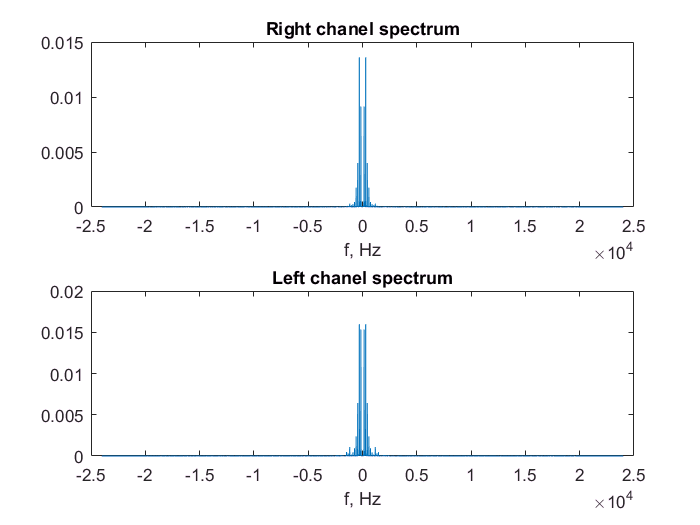

Rs = fft(x(:,1));
Ls = fft(x(:,2));

Rsa = abs(fftshift(Rs)) / N;
Lsa = abs(fftshift(Ls)) / N;

figure
subplot(2,1,1);
plot(f, Rsa);
title('Right chanel spectrum');
xlabel('f, Hz');

subplot(2,1,2);
plot(f, Lsa);
title('Left chanel spectrum');
xlabel('f, Hz');

Отобразим эти спектры в масштабе. 

Обозначим пороговую частоту, до которой нас интересует спектр (Fi - interest frequency) равной 2кГц

Fi = 2e3; 

Нужно найти индекс переменной частоты, которым будет ограничен график (Ni). Зависимость индекса переменной частоты (f) от требуемой частоты (Fi) линейна и может быть выражена следующим выражением для положительных частот

Ni = (N/2) * (1 + Fi/fs);

Для показа положительных частот на графике введу переменную частоты отображающую только положительные частоты ограничиваясь интересующей частотой (Fi).

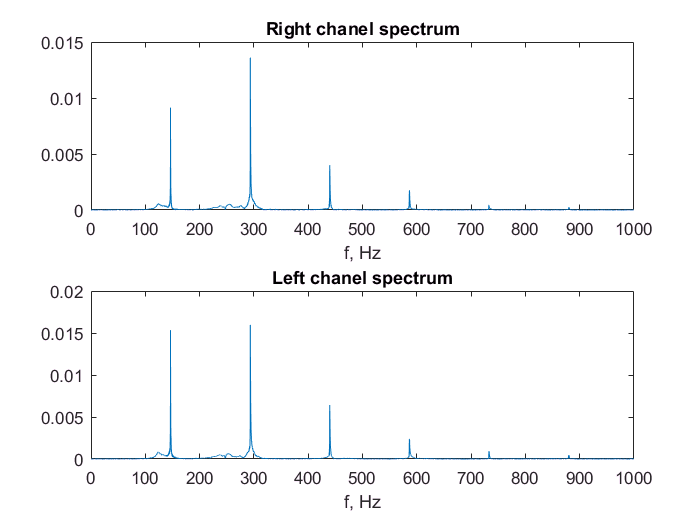

fp   = f  (N/2 + 1: Ni);
Rsap = Rsa(N/2 + 1: Ni);
Lsap = Lsa(N/2 + 1: Ni);

figure
subplot(2,1,1);
plot(fp, Rsap);
title('Right chanel spectrum');
xlabel('f, Hz');

subplot(2,1,2);
plot(fp, Lsap);
title('Left chanel spectrum');
xlabel('f, Hz');

Как видно из графиков спектр ноты РЕ наполнен кратными по частоте гармониками основного тона и характеристика их амплитуд не монотонно затухающая. 

Некоторые векторы достаточно длинные, удалю ненужные для сбережения памяти

clear Rs Ls Rsa Lsa f;

## Найду частоты каждой гармоники. 

Для этого воспользуюсь функцией поиска пиков и задам минимальное расстояние между пиками обеспечивающее игнорирование шума и прочего.

Вектор Fharm будет заполнен частотами гармоник, для перевода частот в индексы используется вектор Nharm. В вектор pks будут записаны высоты каждой гармоники.

[pks, Fharm] = findpeaks(Rsap, fp, 'MinPeakDistance', 100, 'MinPeakHeight', 5e-5);
Nip   = Ni - N/2;
Nharm = floor(Nip * Fharm/Fi);

Вывожу спектр правого канала

figure
area(fp, Rsap);

Поверх него накладываю фигуры, обозначающие положения пиков

hold on
plot(Fharm, pks, 'rv', 'MarkerFaceColor', 'r');

Создаю текст с частотами и накладываю текст на каждый пик спектра. Текст должен быть незначительно выше пиков для повышения читабельности, для чего был введен параметер масштаба yScaleAdd, поднимающий надписи на 5%

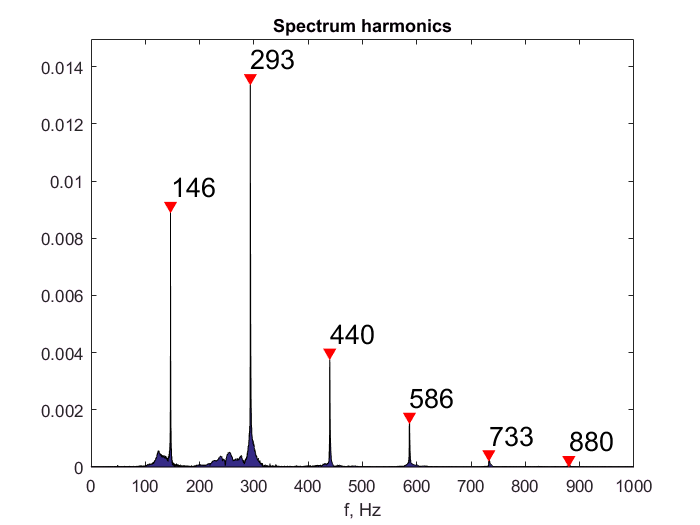

yScaleAdd = max(pks)*0.05; 

cellpeaks = cellstr(num2str(round(Fharm', 0)));
text(Fharm, yScaleAdd+pks, cellpeaks, 'FontSize', 16);
ylim([0 max(pks)+2*yScaleAdd]);
hold off
title('Spectrum harmonics');
xlabel('f, Hz');

Воспользовавшись таблицей соответствия нотам частот можно определить слышимые ноты

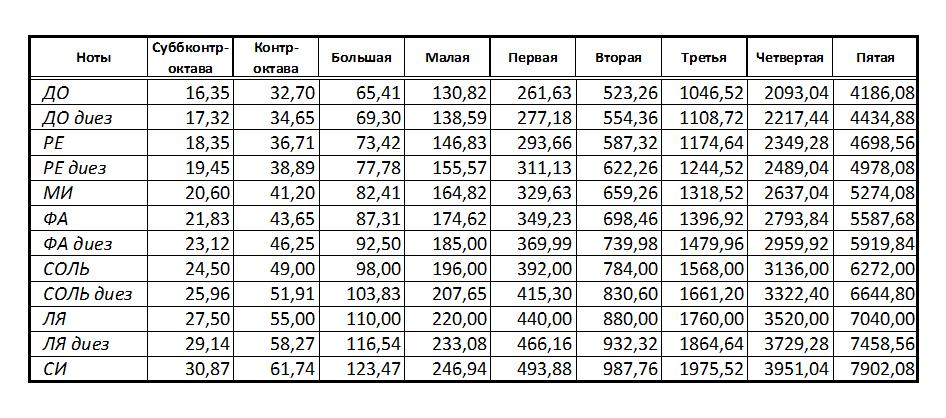

## Найду отношение гармоник к основному тону 

Из пиков видно, что основной тон соответсвует первой гармонике, основной тон обозначу как F0. (Fr - frequency ratio)

F0 = Fharm(1);
Fr = Fharm ./ F0;

strMessage = ['Harmonics frequency ratio ', num2str(Fr)];
disp(strMessage);

Harmonics frequency ratio 1      2.0037      3.0025      4.0049      5.0037      6.0099


С точностью до тысячных частоты гармоник кратные основной.

Найду отношения амплитуд гармоник к амплитуде основной. 

(Ar - amplitude ratio)

Ar = (pks ./ pks(1) )';
strMessage = ['Harmonics amplitude ratio ', num2str(Ar)];
disp(strMessage);

Harmonics amplitude ratio 1      1.4889     0.43814     0.19305    0.049476    0.027427


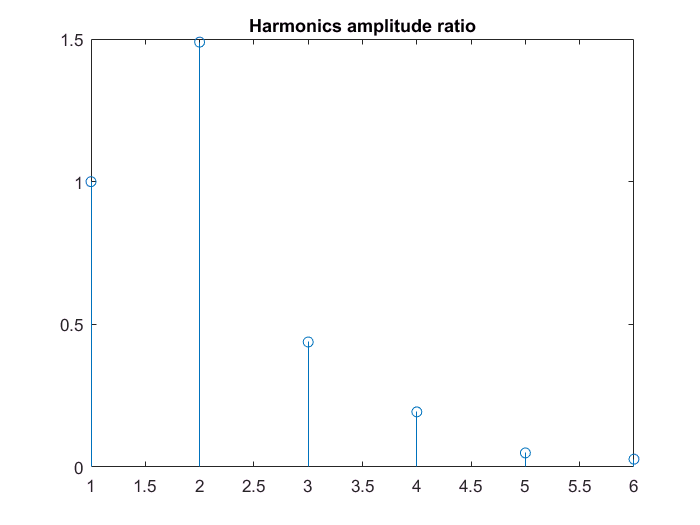


figure
stem(Ar);
title('Harmonics amplitude ratio')

# 2. Временная зависимость амплитуд гармоник

Как известно музыкальные звуки одних и тех же нот отличаются друг от друга на слух раличным тембром. Тембр описывается отношением гармоник и, как утверждают, во времени звучания тембр звука меняется и он меняется уникально для каждого инструмента. В этой части будет найдены временные зависимости тембра.

Такую зависимость можно найти используя оконное преобразование фурье и анализ гармоник, приведенный выше. Так можно получить амплитуды каждой гармоники в заданых временных промежутках и найти их временные изменения. Поскольку нельзя единовременно увеличивать уменьшать шаг частот преобразования фурье и уменьшать время наблюдения - прийдется выбрать оптимальное количество делений звукового сигнала так, что бы спектры временных промежутков несли полезную информациб и качество этой информации было высоким.

Утверждают, что большая часть информации находится в временном промежутке аттаки звука. В этот период темб меняется быстрее всего и несет в себе много информации. А значит длительность аттаки может служить критерием оптимального количества разбитых временных промежутков. 

## Нахожу длительность аттаки

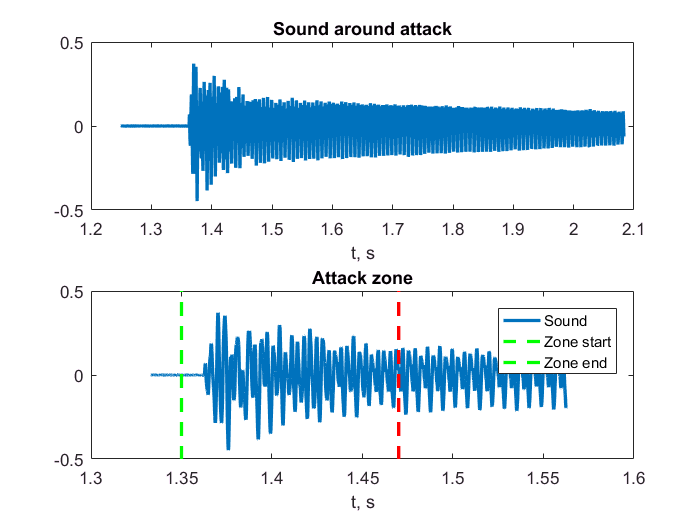

clear all
close all
[x, fs] = audioread('Sound2.m4a');

dt = 1/fs;
N  = length(x);
Ts = (N-1)*dt;
t  = 0:dt:Ts;

StartAttack = ones(100)*1.35;
EndAttack   = ones(100)*1.47;
Amplitude   = linspace(-0.5, 0.5, 100);

figure
subplot(2,1,1);
plot(t(6e4:1:10e4), x(6e4:1:10e4,1), 'LineWidth', 2);     
title('Sound around attack');
xlabel('t, s');

subplot(2,1,2);
plot(t(6.4e4:1:7.5e4), x(6.4e4:1:7.5e4,1), 'LineWidth', 2);    
hold on
plot(StartAttack, Amplitude, '--g', 'LineWidth', 2);
plot(EndAttack, Amplitude, '--r', 'LineWidth', 2);
hold off
title('Attack zone');
xlabel('t, s');
legend('Sound', 'Zone start', 'Zone end');

Экспериментально была найдено, что время аттаки длится примерно 120мс (1350 - 1470). Этот временной промежуток обозначен желтыми линиями на графике. Для получения полезной информации было выбрано разбить участок аттаки минимум на 6 частей (длительностью dT). Найду количество отчетов, попадающих в один временной промежуток (Nw - number of samples in window)

Ta = 0.120;
Na = 6;
dT = Ta / Na; % Time revolution

Nw    = floor((dT/Ts)*N + 1);
Nfrag = floor(N/Nw);

Теперь создаю временную матрицу, где в каждой строке будет Nw отчетов времени, а количеству строк будет соответствовать количесвто фрагментов, на которые разбит аудиофайл

T = reshape(t(1:Nfrag*Nw), Nfrag, Nw);

## Оцениваю разрешение частот

Произведение шага частот на длительность одного временного фрагмента равна 1 по определению. Из чего нахожу шаг частотной сетки.

df = fs / Nw; % Frequency revoltion

Проверка определения (произведение должно быть равным единице)

strMessage = ['df * dT = ', num2str(df * dT)];
disp(strMessage);

df * dT = 0.99896


strMessage = ['Frequency step is ', num2str(df)];
disp(strMessage);

Frequency step is 49.948


Эмпирическим путем было найдено, что если шаг частот меньше половины основного тона - это минимальный удовлетворительный расклад.

## Матрица спектров

Для каждого временного промежутка надо найти спектр и записать его в соответствующей строке матрицы Rs

Rs   = zeros(Nfrag, Nw);
Rsa  = zeros(Nfrag, Nw);
Rsap = zeros(Nfrag, floor(Nw/2));
for i = 1:Nfrag
    ns = (i-1)*Nw + 1;
    ne = i*Nw;
    Rs(i,:)               = fft(x(ns:ne,1));
    Rsa(i,:)              = abs(fftshift(Rs(i,:))) / N;
    Rsap(i,1:floor(Nw/2)) = Rsa(i,floor(Nw/2)+1:Nw-1);
end

fp  = 0:df:fs/2-df;
Fi  = 2e3;
Ni  = floor(Nw*(Fi/fs));

Тут можно просмотреть анимацию изменения спектра по времени

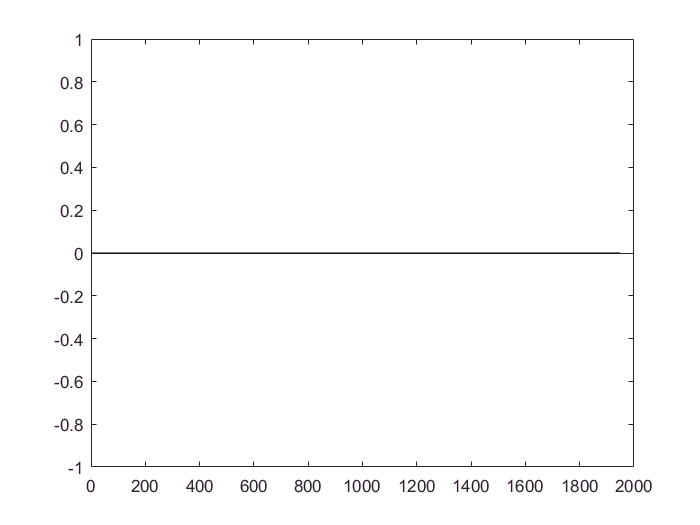

figure

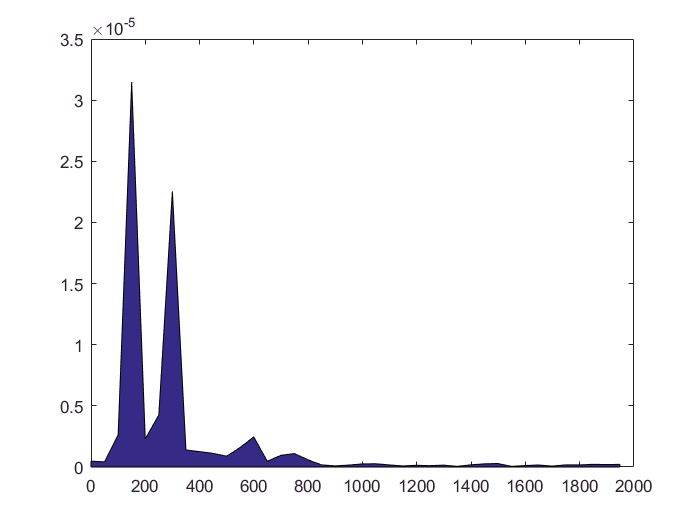

for i = 1:Nfrag  
    area(fp(1:Ni), Rsap(i,1:Ni));
    drawnow
end

Теперь создам матрицу временных зависимостей первых 4 гармоник от времени (т.к. они более выражены) Ввожу уже известные частоты этих гармоник как опорные (reference)

Harm = zeros(4, N);
Fref = [146 293 440 586];

Если выбранный пик соответствует одной из исследуемых гармоник - заполню временное окно (dT) гармоники значением пика (pks).

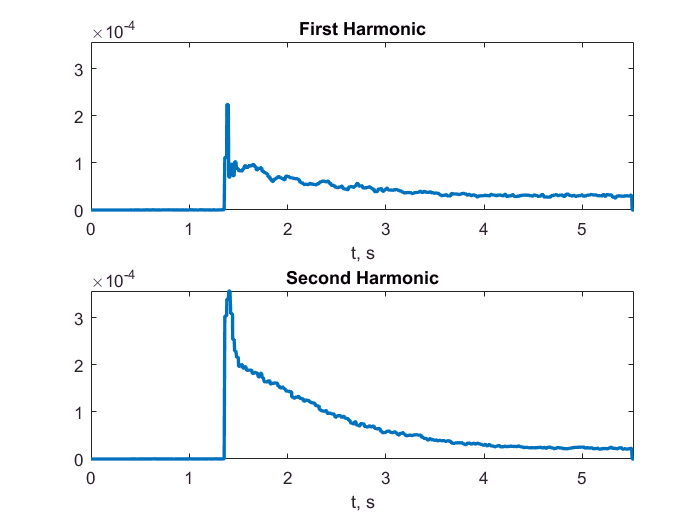

for i = 1:Nfrag
    [pks, Fharm] = findpeaks(Rsap(i,:), fp, 'MinPeakDistance', 60);
    
    for j = 1:length(Fharm)
        for z = 1:length(Fref)
            if abs(Fharm(j) - Fref(z)) < 60
                ns = (i-1)*Nw + 1;
                ne = i*Nw;
                Harm(z, ns:ne) = ones(1,Nw) * pks(j);
            end
        end
    end
end
maxY = max(max(Harm)');

figure
subplot(2,1,1);
plot(t, Harm(1,:), 'LineWidth', 2);     
ylim([0 maxY]);
xlim([0 t(end)]);
title('First Harmonic');
xlabel('t, s');

subplot(2,1,2);
plot(t, Harm(2,:), 'LineWidth', 2);     
ylim([0 maxY]);
xlim([0 t(end)]);
title('Second Harmonic');
xlabel('t, s');

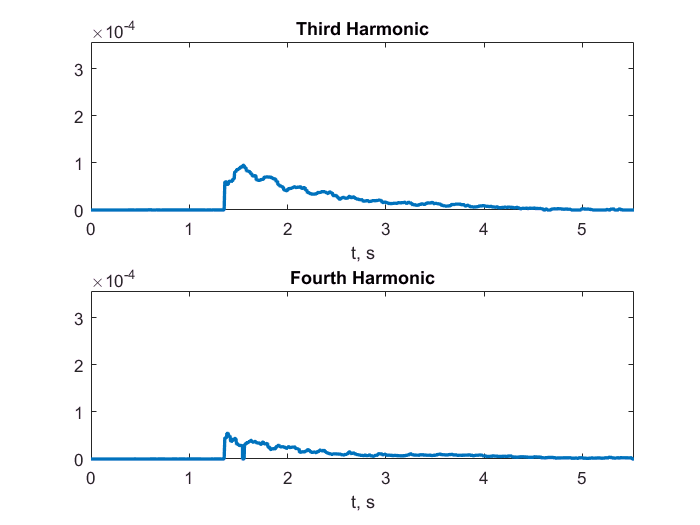


figure
subplot(2,1,1);
plot(t, Harm(3,:), 'LineWidth', 2);     
ylim([0 maxY]);
xlim([0 t(end)]);
title('Third Harmonic');
xlabel('t, s');

subplot(2,1,2);
plot(t, Harm(4,:), 'LineWidth', 2);     
ylim([0 maxY]);
xlim([0 t(end)]);
title('Fourth Harmonic');
xlabel('t, s');

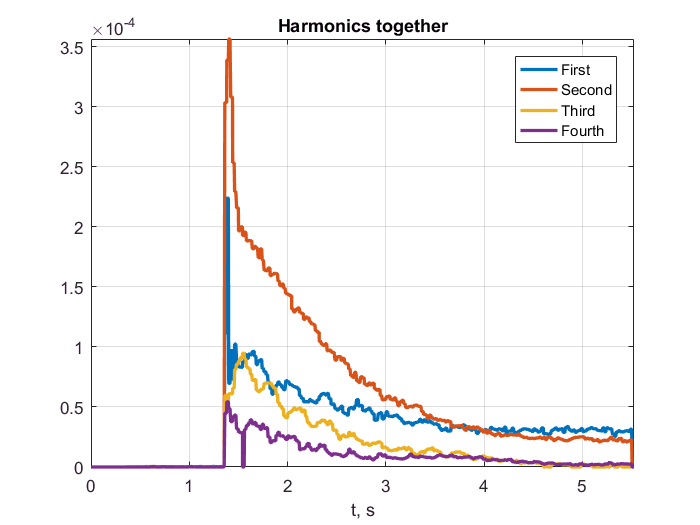


figure
subplot(1,1,1);
plot(t, Harm(1,:), 'LineWidth', 2);
hold on
plot(t, Harm(2,:), 'LineWidth', 2);
plot(t, Harm(3,:), 'LineWidth', 2);
plot(t, Harm(4,:), 'LineWidth', 2);
ylim([0 maxY]);
xlim([0 t(end)]);
grid on
title('Harmonics together');
xlabel('t, s');
legend('First', 'Second', 'Third', 'Fourth');

Покажу изменение во времени тембра, то есть отношения гармоник

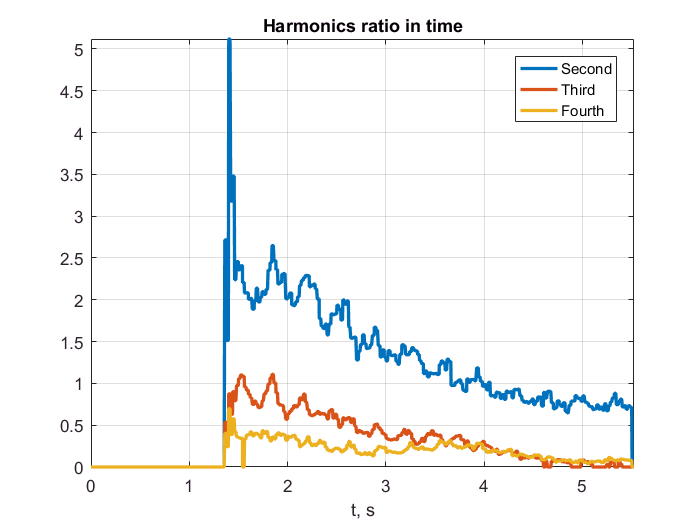

for i = 1:3
    for j = 1:N
        if Harm(i+1, j) < 7e-7 || Harm(1,j) < 7e-7
            Ar(i,j) = 0;
        else
            Ar(i,j) = Harm(i+1,j) ./ Harm(1,j);
        end
    end
    
end

maxY = max(max(Ar)');

figure
subplot(1,1,1);
plot(t, Ar(1,:), 'LineWidth', 2);
hold on
plot(t, Ar(2,:), 'LineWidth', 2);
plot(t, Ar(3,:), 'LineWidth', 2);
ylim([0 maxY]);
xlim([0 t(end)]);
grid on
title('Harmonics ratio in time');
xlabel('t, s');
legend('Second', 'Third', 'Fourth');

Можно сравнить полученные результаты отношения гармоник с полученными ранее для всей длительности сигнала. Временное проедставление отношения гармоник дает намного больше полезной информации о тембре

## Обратный синтез с потерями фазы

Воссоздаю обратно звук как сумму этих гармоник. Звук должен отличаться от гитарной струны, но и чем то быть похожим

Синтез звука

NewSound = zeros(1,N);

for i = 1:4
    NewSound = NewSound + Harm(i,:) .* sin(Fharm(i)*2*pi*t);
end

Gain

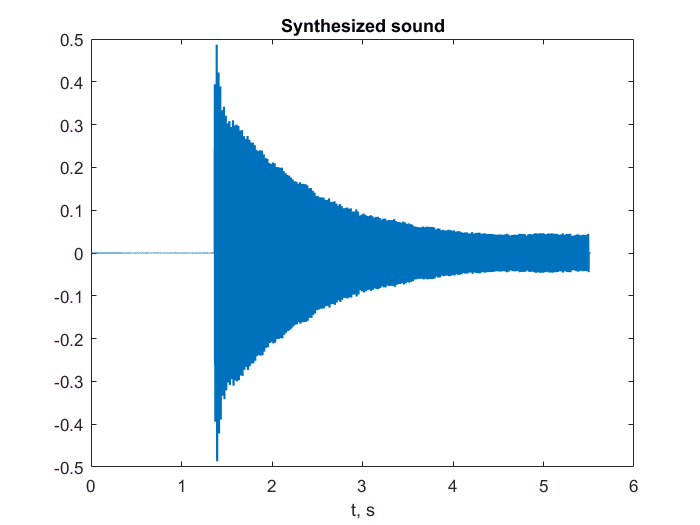

Gain = 1e3;
NewSound = NewSound .* Gain;

figure
plot(t, NewSound);
xlabel('t, s');
title('Synthesized sound');

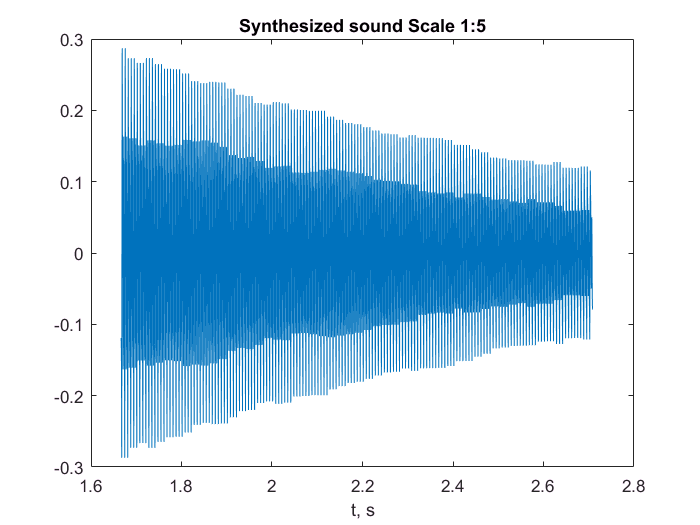


figure
plot(t(8e4:13e4), NewSound(8e4:13e4));
xlabel('t, s');
title('Synthesized sound Scale 1:5');

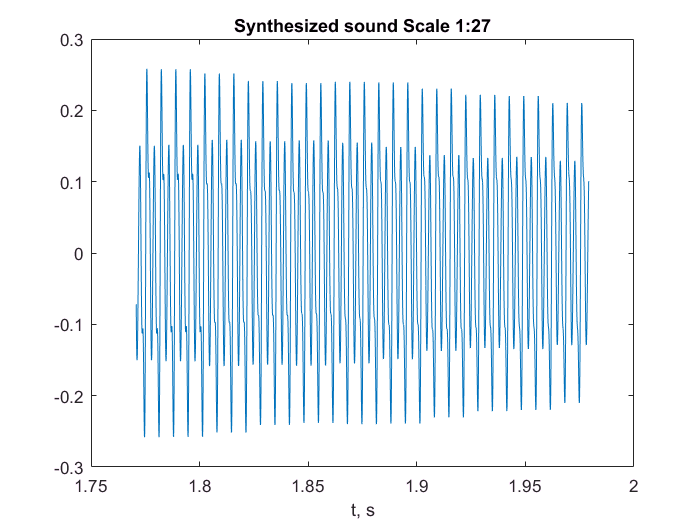


figure
plot(t(85e3:95e3), NewSound(85e3:95e3));
xlabel('t, s');
title('Synthesized sound Scale 1:27');


sound(NewSound, fs);

## Обратный синтез с учетом фазы

При мат анализе выше использовался только правый канал звукоряда и при исследовании спектра использовался его модуль, чем была проигнорирована фаза. Повторю все действия без потери фазы и при обратном синтезе воссоздам спектр только из гармоник и получу синтезированный звук обратным преобразованием фурье.

(Rs - right spectrum)

Rs = zeros(Nfrag, Nw);
Ls = zeros(Nfrag, Nw);
Rsap = zeros(Nfrag, floor(Nw/2));
for i = 1:Nfrag
    ns = (i-1)*Nw + 1;
    ne = i*Nw;
    Rs(i,:)  = fft(x(ns:ne,1));
    Ls(i,:)  = fft(x(ns:ne,2));
end

Собираю временные зависимости каждой из гармоник каждого канала в комплексном виде, не упуская фазу

HarmR = zeros(4, N);
HarmL = zeros(4, N);
Fref = [146 293 440 586];
f    = -fs/2:df:fs/2 - df;

for i = 1:Nfrag
    [pksR, FharmR] = findpeaks(fftshift(abs(Rs(i,:))), f, 'MinPeakDistance', 60);
    [pksL, FharmL] = findpeaks(fftshift(abs(Ls(i,:))), f, 'MinPeakDistance', 60);
    
    for j = 1:length(Fharm)
        for z = 1:length(Fref)
            
            if length(FharmR) > j-1
                if abs(FharmR(j) - Fref(z)) < 60
                    ns = (i-1)*Nw + 1;
                    ne = i*Nw;
                    Nr = floor(Nw * FharmR(j)/fs + 1 + Nw/2);
                    HarmR(z, ns:ne) = ones(1,Nw) * Rs(i,Nr);
                end
            end
            
            if length(FharmL) > j-1
                if abs(FharmL(j) - Fref(z)) < 60
                    ns = (i-1)*Nw + 1;
                    ne = i*Nw;
                    Nl = floor(Nw * FharmL(j)/fs + 1 + Nw/2);
                    HarmL(z, ns:ne) = ones(1,Nw) * Ls(i,Nl);
                end
            end
            
        end
    end
end

На каждое временное окно наблюдения создаю свой спектр, получаю матрицу спектров для каждого промежутка времени. После чего получу звукоряд для каждого промежутка и объединю его в один вектор звукоряда

Не использовать код. Зависает компьютер!!!

SpecR  = zeros(Nfrag, Nw);
SpecL  = zeros(Nfrag, Nw);

for i = 1:Nfrag
    for j = 1:Nw
        for z = 1:4
            
            Nf    = floor(Nw * FharmL(z)/fs + 1 + Nw/2);
            Nharm = floor(j + (i-1) * Nw)
            SpecR(Nf)      = SpecR(Nf) + HarmR(z, Nharm);
            SpecR(Nw - Nf) = SpecR(Nf);
            
            SpecL(Nf)      = SpecL(Nf) + HarmL(z, Nharm);
            SpecL(Nw - Nf) = SpecL(Nf);
            
        end
    end
end

Nharm = 1

Subscript indices must either be real positive integers or logicals.


Получаю левый и правый канал

SoundR = ifft(fftshift(SpecR));
SoundL = ifft(fftshift(SpecL));

figure
plot(t, SoundR);
xlabel('t, s');
title('Synthesized sound');

figure
plot(t(8e4:13e4), SoundR(8e4:13e4));
xlabel('t, s');
title('Synthesized sound Scale 1:5');

figure
plot(t(85e3:95e3), SoundR(85e3:95e3));
xlabel('t, s');
title('Synthesized sound Scale 1:27');

Sound  = [SoundR; SoundL]

# 3. Изменение тембра методом апроксимации кубическими сплайнами

Повторю нахождение временных зависимостей амплитуд гармоник, найденых во 2 пункте и вместо прямого их использования в качестве амплитуд гармонических колебаний сперва интерполирую их сплайнами тем самым повысив частоту дискретизации и, возможно, улучшив качество звука.